variable = "DENSITY"

    "Directory already exists: "    "DMD_28_2_2025"



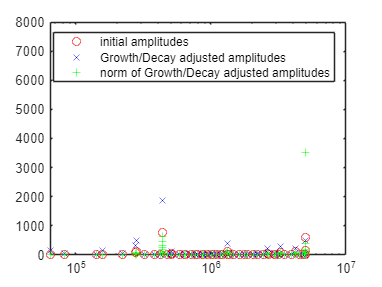

variable = "PRESSURE"

    "Directory already exists: "    "DMD_28_2_2025"



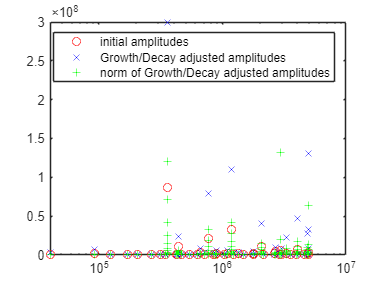

variable = "MASSFRAC_C3H8"

    "Directory already exists: "    "DMD_28_2_2025"



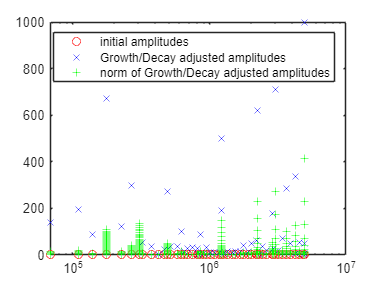

variable = "VELOCITY_X"

    "Directory already exists: "    "DMD_28_2_2025"



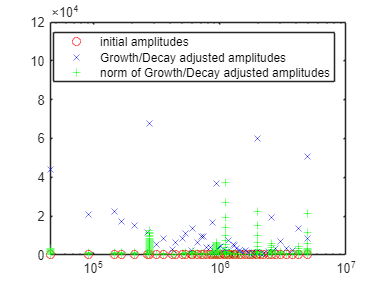

variable = "VELOCITY_Y"

    "Directory already exists: "    "DMD_28_2_2025"



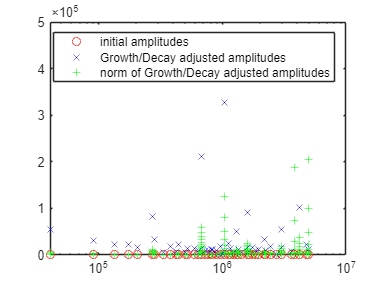

variable = "VELOCITY_Z"

    "Directory already exists: "    "DMD_28_2_2025"



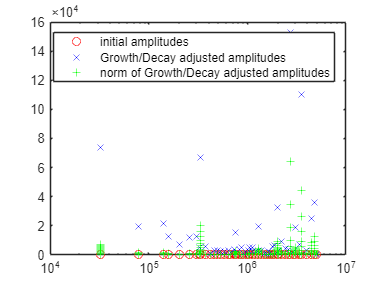

variable = "VORTICITY_X"

    "Directory already exists: "    "DMD_28_2_2025"



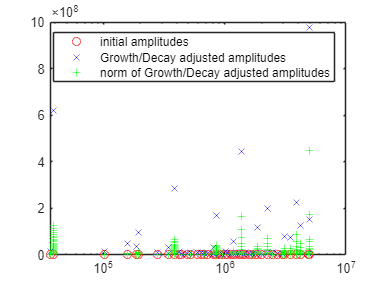

variable = "VORTICITY_Y"

    "Directory already exists: "    "DMD_28_2_2025"



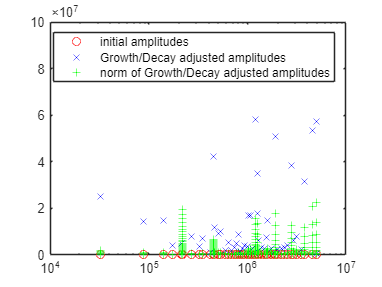

variable = "VORTICITY_Z"

    "Directory already exists: "    "DMD_28_2_2025"



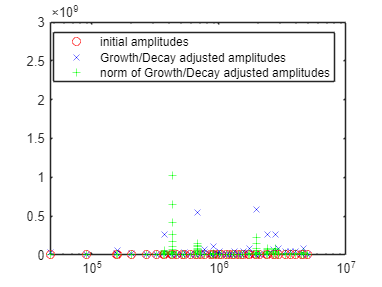

variable = "TEMPERATURE"

    "Directory already exists: "    "DMD_28_2_2025"



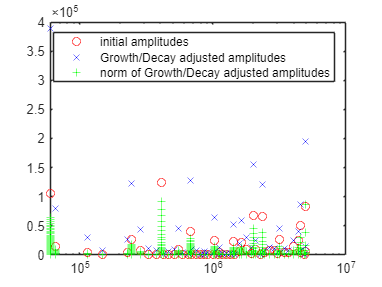

variables = ["DENSITY";
"PRESSURE"
% "MASSFRAC_O2";
% "MASSFRAC_H2O";
% "MASSFRAC_CO";
% "MASSFRAC_CO2";
"MASSFRAC_C3H8";
"VELOCITY_X";
"VELOCITY_Y";
"VELOCITY_Z";
"VORTICITY_X";
"VORTICITY_Y";
"VORTICITY_Z";
"TEMPERATURE"];

caseName = "_snapshot_matrix";
directoryName = "snaphsot_matricies";
save_directoryName = "DMD_28_2_2025";
dt = .1E-6;

% perform the DMD
for i = 1:length(variables)
    variable = variables(i)
    DMD_driver(variable, caseName, directoryName, save_directoryName, dt)
end

## Plot the results

variable = "DENSITY"

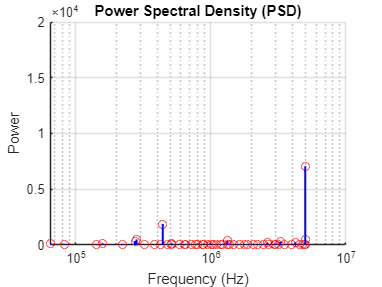

variable = "PRESSURE"

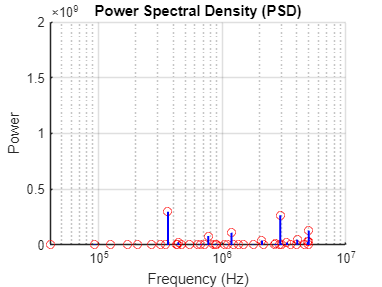

variable = "MASSFRAC_C3H8"

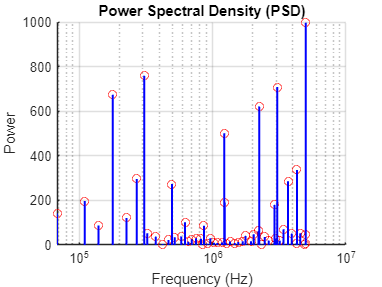

variable = "VELOCITY_X"

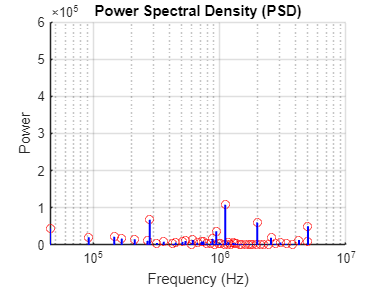

variable = "VELOCITY_Y"

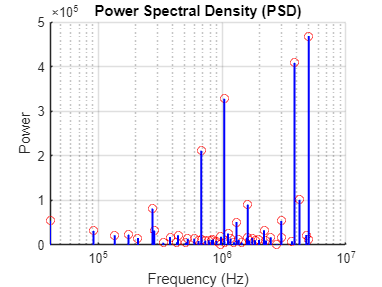

variable = "VELOCITY_Z"

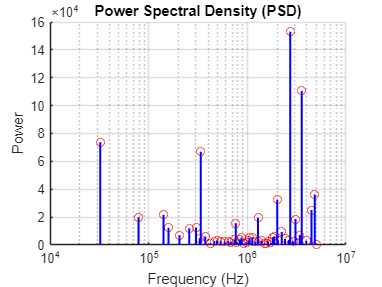

variable = "VORTICITY_X"

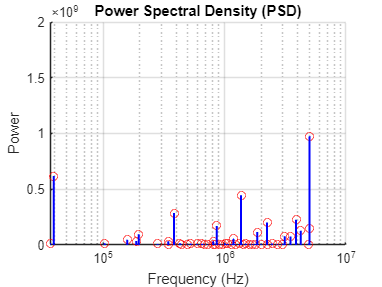

variable = "VORTICITY_Y"

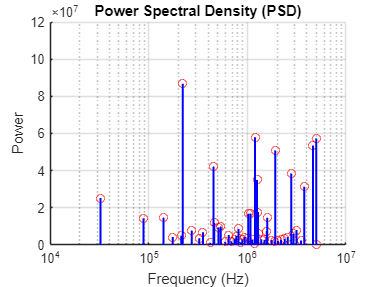

variable = "VORTICITY_Z"

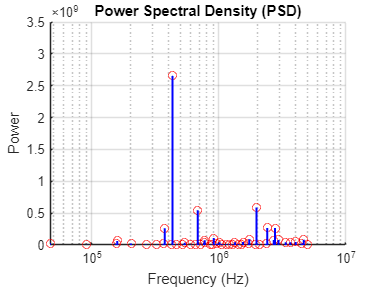

variable = "TEMPERATURE"

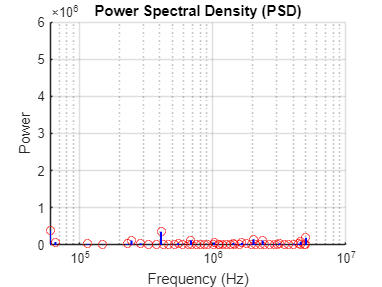


for i = 1:length(variables)
    variable = variables(i)
    load(save_directoryName+"/"+caseName+variable+"results.mat")
    % figure;
    % plot(real(timeDynamics)');
    % drawnow;

    figure;
    scatter(abs(imag(contTimeEigVals)), DMDpower,"ro")
    hold on
    for i = 1:length(contTimeEigVals)
        line([abs(imag(contTimeEigVals(i))), abs(imag(contTimeEigVals(i)))], [0, DMDpower(i)], 'Color', 'b', 'LineWidth', 1.5);
    end
    xlabel('Frequency (Hz)');
    ylabel('Power');
    title('Power Spectral Density (PSD)');
    set(gca, 'XScale', 'log');  % Set x-axis to logarithmic scale
    grid on;
    hold off;
end